# Kalman Filter for Rocket

A Kalman filter is a useful tool for combining both measurements and modeling into a single refined state estimate technique. Running a Kalman filter on the rocket could be useful for more accurately detecting apogee as well as getting a better idea of how high the rocket goes.

The first thing to do is to make some fake sensor data. This was done by solving a second order equation of motion of an object. Note that this model considers air resistance. The output of this model is displayed below.

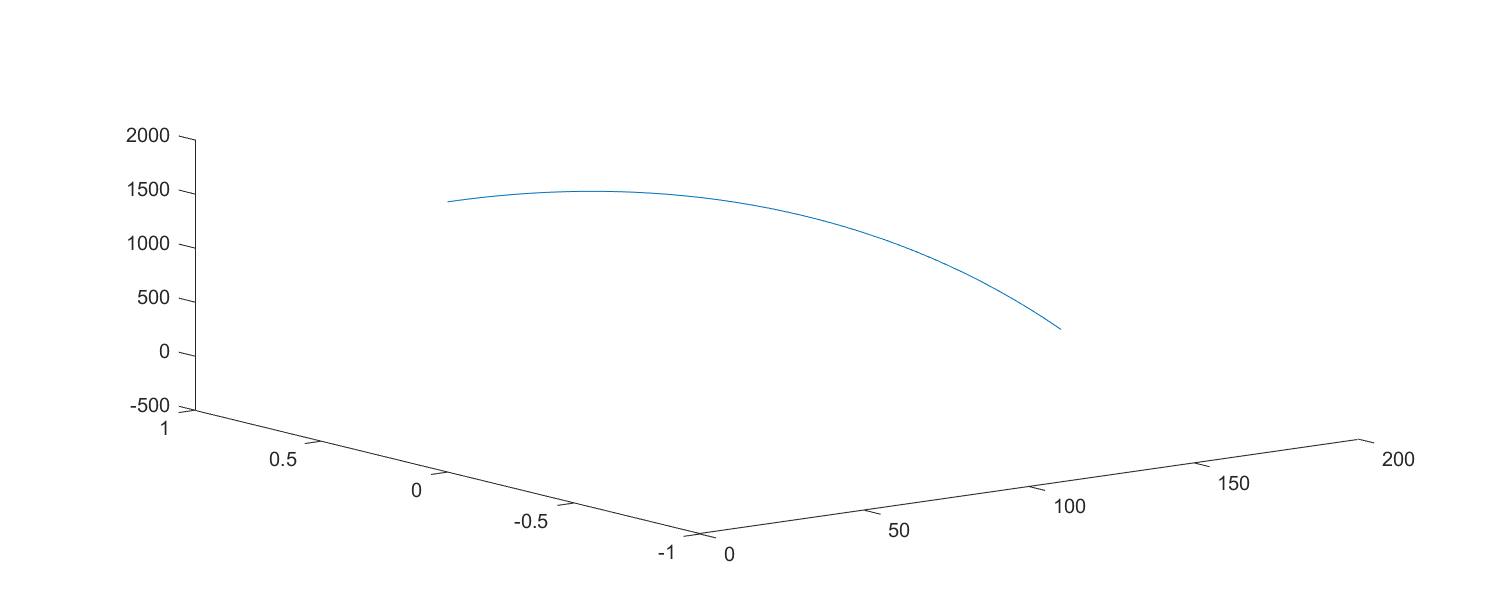

%run simple model to generate fake positoin data for rocket
dt = 0.1;
[T, D] = altitude_model(dt);  %dt

For the filter we will first only consider the z position since this can be measured with a barometer chip. We will also use the vertical acceleration which can be measured with an accelerometer(?). To make the fake sensor data, we will add some normally distributed noise with a standard deviation of 10.

The fake sensor data is plotted below.

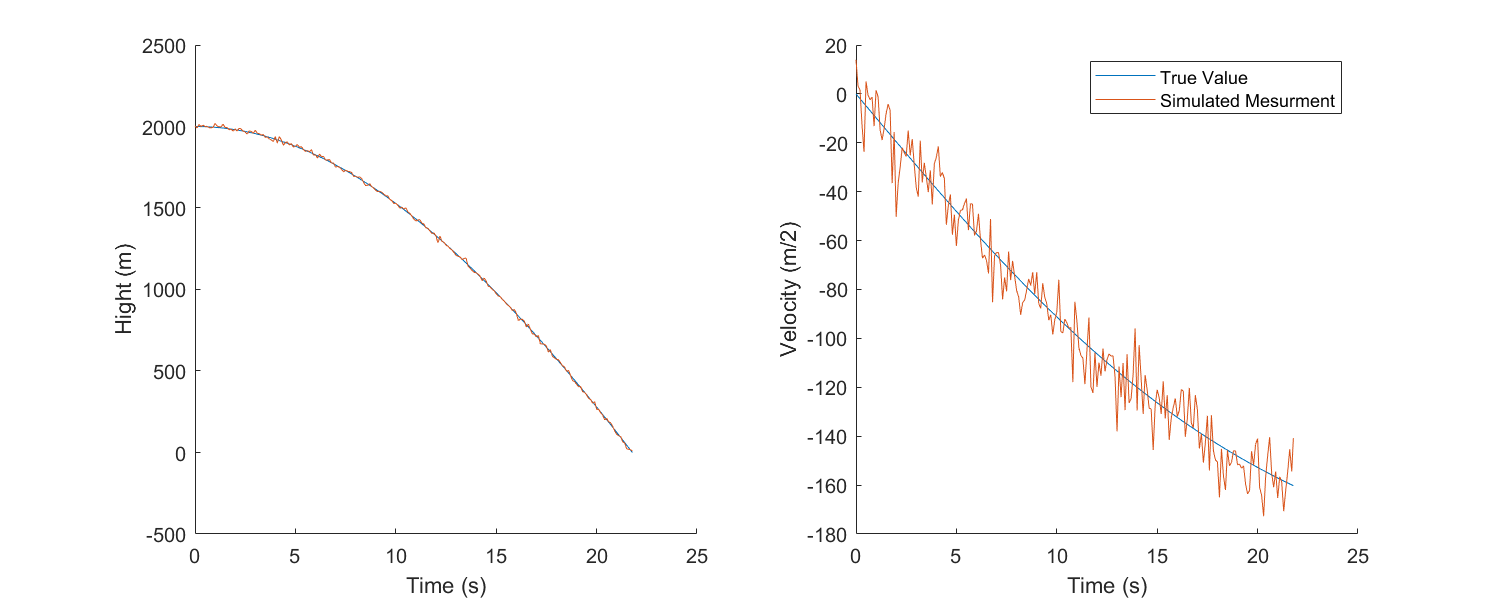

true_state = [D(:,3), D(:,6)]; %extract z position and velocity data
%create normal distributed noise
sigma = 10;
noise = sigma*randn(size(true_state));
%add noise to data
noise_state = true_state + noise;

%plotting
figure(1)
clf
set(figure(1), "Position", [0 0 1000, 400])
subplot(1,2,1)
hold on
plot(T, true_state(:,1))
plot(T, noise_state(:,1))
hold off
xlabel("Time (s)")
ylabel("Hight (m)")


subplot(1,2,2)
hold on
plot(T, true_state(:,2))
plot(T, noise_state(:,2))
hold off
xlabel("Time (s)")
ylabel("Velocity (m/2)")
legend("True Value", "Simulated Mesurment")

The algorithm works by feeding the filter function the current “best-guess” at what the state of the system is (`state:` a vector containing vertical position and velocity). We also feed in our “best guess” for what the prediction covariance matrix (`p_cov`) of the state is. Essentially, we are making a guess and then guessing at how good our first guess is…

Finally, we feed the Kalman filter a new measurement of the state. In this case, this is just the next elements in the fake sensor data.

The `kalman_update` function takes all this information, does some fancy linear algebra (which we can talk about latter), and spits out a new state/”best-guess” as well as a new covariance matrix for that state.

We can keep calling the function for as many sensor data points as we have. We should also write the state after each iteration to a matrix so we can plot it latter.

Mean Kalman position error: 3.0854m
Mean Sensor position error: 7.9433m
Mean Kalman velocity error: 3.3225m/s
Mean Sensor velocity error: 7.113m/s


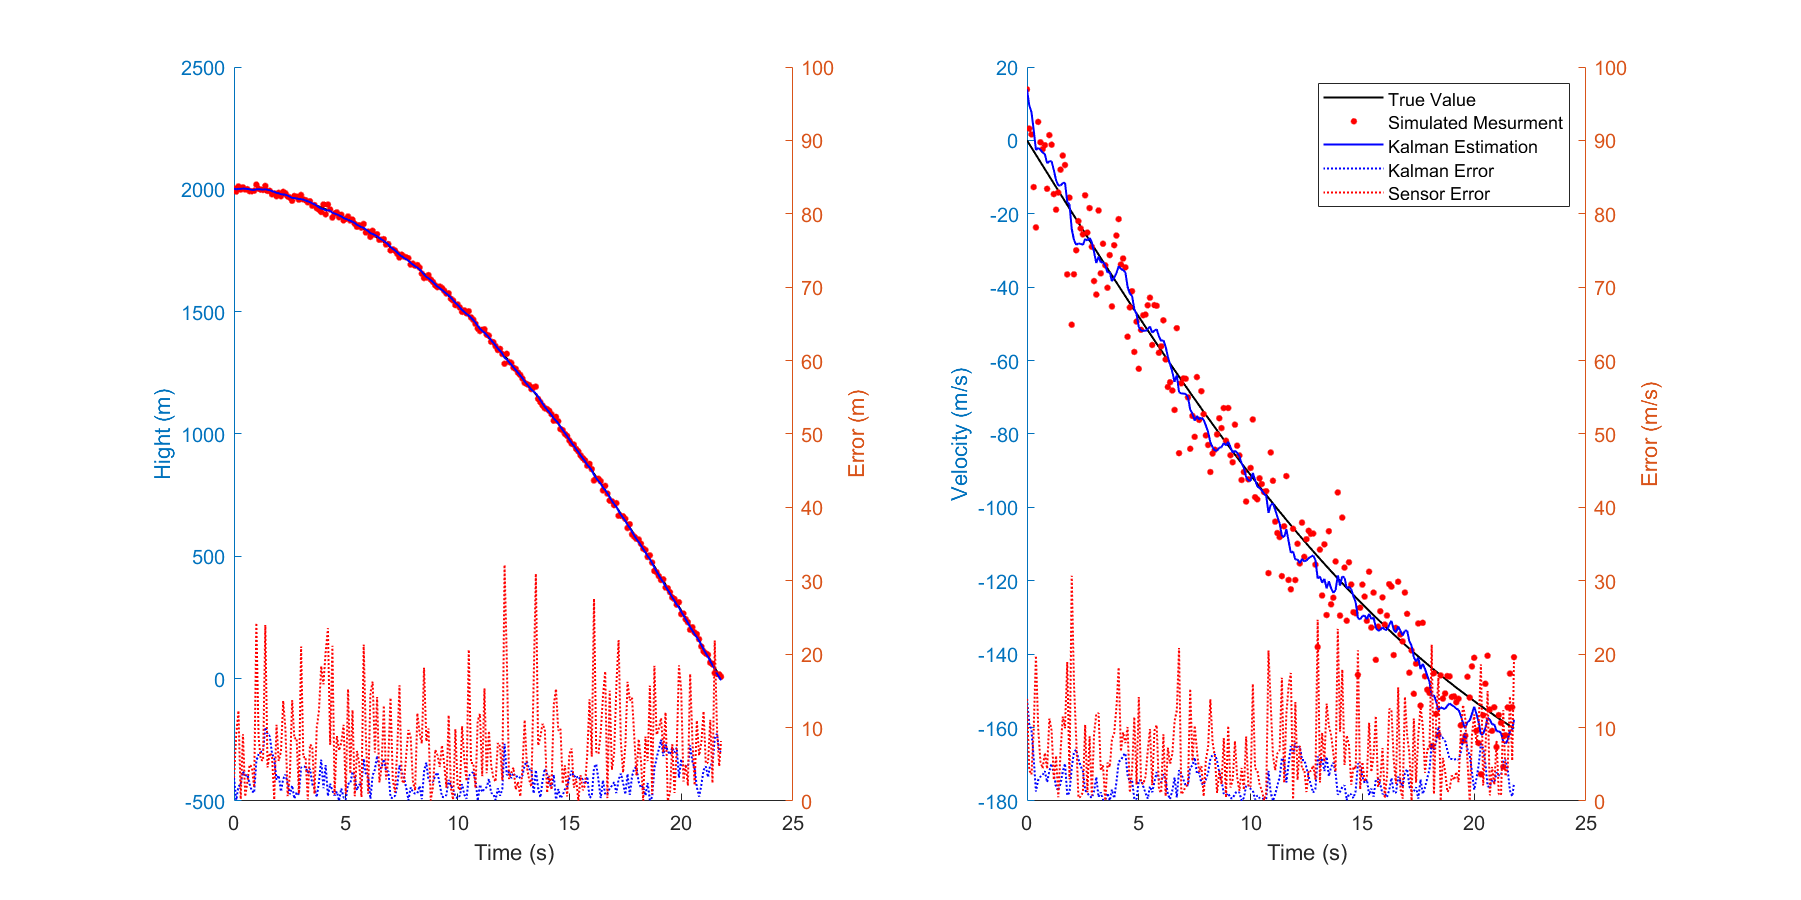

%define some global matricies
global A B H R Q MU;
A = [1 dt ; 0 1];
B = [0.5 * dt^2 ; dt];
H = [1 0 ; 0 1];
R = 100*eye(2);  %measurement noise covarience (from the sensor: in this case sigam^2)
Q = 25*eye(2); %proccess noise covarience (from perturbations like aerodynamic drag)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;


%set inital state and proccess covariance to first measurement
state = noise_state(1,:)';
p_cov = Q;

%make some empty arrays
kalman_state = zeros(size(noise_state));
kalman_state(1,:) = noise_state(1,:);

%loop through all mesurments and run filter
for i=2:length(noise_state)
    measurement = noise_state(i,:)';
    [state, p_cov] = kalman_update(state, p_cov, measurement);
    kalman_state(i,:) = state';
end

%plot results
plot_res(T, true_state, noise_state, kalman_state)

In the above example, we see that the Kalman filter is abount twice as accurate as using the sensor data alone. We can tune the filter by adjusting the R matrix. This is the process covariance noise, and it encodes how much uncertainty there is in the built-in model that runs inside the Kalman filter. Because this model does not consider the air resistance, we are effectively using R to tell the kalman filter to not get to comfortable trusting only the simple model.

You can see that changing the value of R make the Kalman filter move between following the sensor data and following the internal model (not shown) more closely.